# Radar Signal Processing Verification

This script has been written to confirm that the signal processing component of a radar is working as anticipated

## Initialize the simulator

clear;
simulator = Simulator_revB();
file_path = "/home/david/Documents/RadarSecurityResearch/MATLAB/Simulink Model/config_files/B210_params.json";
% file_path = "/home/david/Documents/RadarSecurityResearch/MATLAB/Simulink Model/config_files/B210_params_highBW.json";
% file_path = "/home/david/Documents/RadarSecurityResearch/MATLAB/Simulink Model/config_files/B210_params_highvres.json";
% file_path = "/home/david/Documents/RadarSecurityResearch/MATLAB/Simulink Model/config_files/B210_params_lowBW.json";
% file_path = "/home/david/Documents/RadarSecurityResearch/MATLAB/Simulink Model/config_files/B210_params_sensing_system.json";
% file_path = "/home/david/Documents/RadarSecurityResearch/MATLAB/Simulink Model/config_files/X310_params_100MHzBW.json";
% file_path = "/home/david/Documents/RadarSecurityResearch/MATLAB/Simulink Model/config_files/realistic_params.json";
simulator.load_params_from_JSON(file_path);


%apply timing offsets as desired
simulator.Victim.timing_offset_us = 0;
simulator.Attacker.Subsystem_tracking.timing_offset_us = 0;

%configure the FMCW parameters
simulator.configure_FMCW_Radar_parameters();

%load default attacker, and victim positions and velocities
simulator.load_realistic_attacker_and_victim_position_and_velocity();

%print out key parameters
simulator.Victim.print_chirp_parameters;

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.20 MHz/us
	 Idle Time: 			 1.95 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.49 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 1.54 MSps
	 Ramp End Time: 		 48.05 us
	 Chirp Tx Bandwidth: 		 57.66 MHz
	 Chirp Sampling Bandwidth: 	 49.87 MHz
	 ADC Sampling Period: 		 41.56 us
	 Chirp Cycle Time: 		 50.00 us
	 Chirp Wavelength: 		 3.89 mm



simulator.Victim.print_frame_parameters;

Frame Parameters
	 Number of Chirps 		 64
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.20 ms


simulator.Victim.print_performance_specs;

Performance Specifications
	 Max Range 			 192.37 m
	 Range Resolution 		 3.01 m
	 Max Velocity 			 19.47 m/s
	 Velocity Resolution 		 0.61 m/s


simulator.Victim.print_FMCW_specs;

FMCW Specifications
	 FMCW sampling rate 		 58.52 MHz
	 Downsampling factor 		 38
	 Sweep time 			 48.05 us
	 Samples per chirp 		 2926.00 


## Initialize the Target Emulator

target_range = 70; %m
target_velocity = 15; % m/s
emulated_target = FMCW_Emulator_revA(simulator.Victim,target_range,target_velocity,"target");

Writing code to simulate the signal propogation through the signal processing chain

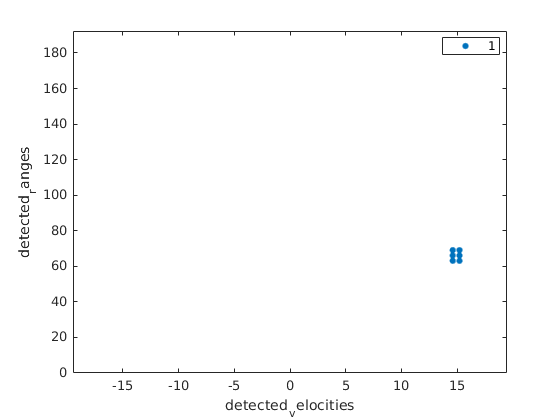

%specify the number of frames and chirps to compute
frames_to_compute = 6;
chirps_to_compute = simulator.Victim.NumChirps;

%get the radar chirp generator and the target emulator ready
emulated_target.reset_emulated_chirp_computation();
simulator.Victim.precompute_radar_chirps();


%configure things to be able to generate a movie
F_rngdop(frames_to_compute) = struct('cdata',[],'colormap',[]);
F_clusters(frames_to_compute) = struct('cdata',[],'colormap',[]);

for frame = int32(1:frames_to_compute)
    
    %compute the emulated chirps for the current frame
    emulated_target.compute_next_emulated_chirps();

    %initialize a clean radar cube
    radar_cube = zeros(simulator.Victim.ADC_Samples,simulator.Victim.NumChirps);
    
    for chirp = int32(1:chirps_to_compute)
    
        %get the Tx chirp and the chirp received from the emulator
        Rx_sig = emulated_target.emulated_chirps(:,chirp);
        Tx_sig = simulator.Victim.chirps(:,chirp);      
        
        %dechirp and downsample the signal
        sampled_IF_sig = simulator.Victim.Radar_Signal_Processor.FMCW_dechirp_and_decimate(Tx_sig,Rx_sig);
        
        %assemble the radar cube
        radar_cube(:,chirp) = sampled_IF_sig;
    end
    
    %range-doppler response
    [resp, rnggrid,dopgrid] = simulator.Victim.Radar_Signal_Processor.RangeDopplerResponse(radar_cube);

    %plot the doppler response and save it for a movie
    plotResponse(simulator.Victim.Radar_Signal_Processor.RangeDopplerResponse,radar_cube);
    drawnow
    F_rngdop(frame) = getframe(gcf);
    
    %CA CFAR 2-D
    detections = simulator.Victim.Radar_Signal_Processor.CFARDetector2D(abs(resp).^2,simulator.Victim.Radar_Signal_Processor.CUT_indicies);
    detected_velocities = dopgrid(detections(2,:));
    detected_ranges = rnggrid(detections(1,:));
    
    %DBSCAN Clustering
    idx = dbscan(detections.',simulator.Victim.Radar_Signal_Processor.Epsilon,simulator.Victim.Radar_Signal_Processor.minpts);

    %plot the clusters
    gscatter(detected_velocities,detected_ranges,idx);
    axis([-1 * simulator.Victim.V_Max_m_per_s, simulator.Victim.V_Max_m_per_s, 0,simulator.Victim.Range_Max_m]);
    drawnow
    F_clusters(frame) = getframe(gcf);

    %estimate the range and the velocities
    rngest = simulator.Victim.Radar_Signal_Processor.RangeEstimator(resp,rnggrid,detections,idx.');
    dopest = simulator.Victim.Radar_Signal_Processor.DopplerEstimator(resp,dopgrid,detections,idx.');
end

%play the movie for the range doppler
% fig = figure;
% movie(fig,F_rngdop,1,1)

%play the movie for the clusters
% fig = figure;
% movie(fig,F_clusters,1,1)


## Simulink Model

### Initialize Simulink Model

%initialize other variables needed in the simulation

%initialization for the target emulator
emulated_chirps = emulated_target.emulated_chirps;
emulated_target.reset_emulated_chirp_computation();
emulated_target.compute_next_emulated_chirps();
emulated_chirps_size = size(emulated_target.emulated_chirps);

%initialization for the Chirp Generator
chirps = simulator.Victim.chirps;

%for the radar modules
num_samples_prior_to_sample_period = simulator.Victim.Radar_Signal_Processor.num_samples_prior_to_sample_period;
num_samples_in_sampling_period = simulator.Victim.Radar_Signal_Processor.num_samples_in_sampling_period;

victim_num_adc_samples = simulator.Victim.ADC_Samples;


%open the simulink model

open_system('Radar_Signal_Processing');
stop_time = frames_to_compute * simulator.Victim.FramePeriodicity_ms * 1e-3;

%the stop time has to be adjusted due to the way that simulink sets up
%timing
stop_time = ceil(stop_time/(simulator.Victim.NumChirps * simulator.Victim.ChirpCycleTime_us * 1e-6))...
    * simulator.Victim.NumChirps * simulator.Victim.ChirpCycleTime_us * 1e-6;
% stop_time = (frames_to_compute - 1) * simulator.Victim.FramePeriodicity_ms * 1e-3...
%     + (chirps_to_compute * simulator.Victim.ChirpCycleTime_us * 1e-6);
set_param('Radar_Signal_Processing','StopTime','stop_time');
warning_to_suppress_id = 'Coder:MATLAB:illConditionedMatrix';
warning('off',warning_to_suppress_id);
out = sim('Radar_Signal_Processing','SimulationMode','accelerator','SaveOutput','on');

### Tx Sig and Rx Sig

These are for diagnostics, not using these unless needing to debug. Keep in mind that due to the simulink timing, you will have to adjust the stop time of the simulation for these to be correct

% Tx_sig_simulink = out.Tx_sig(:,:,1);
% Rx_sig_simulink = out.Rx_sig(:,:,1);
% 
% %compare = all(abs(Tx_sig - Tx_sig_simulink) < 1e-5,'all');
% compare = all(Tx_sig == Tx_sig_simulink,'all');
% if compare
%     fprintf("Tx Sig: \t\t Matches")
% else
%     fprintf("Tx Sig: \t\t Does Not Match")
% end
% compare = all(Rx_sig == Rx_sig_simulink,'all');
% if compare
%     fprintf("Rx Sig: \t\t Matches")
% else
%     fprintf("Rx Sig: \t\t Does Not Match")
% end

### Sampled IF Signal

% sampled_IF_sig_simulink = out.sampled_IF_sig(:,:,1);
% compare = all(sampled_IF_sig == sampled_IF_sig_simulink,'all');
% 
% if compare
%     fprintf("Sampled IF Signal: \t\t Matches")
% else
%     fprintf("Sampled IF Signal: \t\t Does Not Match")
% end

### Radar Cube

%check a few chirps later to ensure that no timing errors or drift
radar_cube_simulink = out.radar_cube(:,:,2);
compare = all(abs(radar_cube - radar_cube_simulink) < 1e-10,'all');

if compare
    fprintf("Radar Cube: \t\t Matches")
else
    fprintf("Radar Cube: \t\t Does Not Match")
end

### Range Doppler Response

%check a few chirps later to ensure that no timing errors or drift
radar_cube_simulink = out.radar_cube(:,:,2);
compare = all(abs(radar_cube - radar_cube_simulink) < 1e-10,'all');

if compare
    fprintf("Range Doppler Response: \t\t Matches")
else
    fprintf("Range Doppler Response: \t\t Does Not Match")
end

### CFAR Detections

%check a few chirps later to ensure that no timing errors or drift
detections_simulink = out.detections(:,:,2);
compare = all(detections == detections_simulink(:,~isnan(detections_simulink(1,:))),'all');

if compare
    fprintf("CFAR Detections: \t\t Matches")
else
    fprintf("CFAR Detections: \t\t Does Not Match")
end

### Clustering

%check a few chirps later to ensure that no timing errors or drift
idx_simulink = out.idx(:,:,2);
compare = all(idx == idx_simulink(:,~isnan(idx_simulink(1,:))),'all');

if compare
    fprintf("Clustering: \t\t Matches")
else
    fprintf("Clustering: \t\t Does Not Match")
end

### Range and Velocity Estimates

%check a few chirps later to ensure that no timing errors or drift
rngest_simulink = out.rngest(:,:,2);
dopest_simulink = out.dopest(:,:,2);

compare = all(abs(rngest(~isnan(rngest)) - rngest_simulink(~isnan(rngest_simulink))) < 1e-10,'all');
if compare
    fprintf("Range Estimate: \t\t Matches")
else
    fprintf("Range Estimate: \t\t Does Not Match")
end

compare = all(abs(dopest(~isnan(dopest)) - dopest_simulink(~isnan(dopest_simulink))) < 1e-10,'all');
if compare
    fprintf("Velocity Estimate: \t\t Matches")
else
    fprintf("Velocity Estimate: \t\t Does Not Match")
end